# **生成干涉图像**

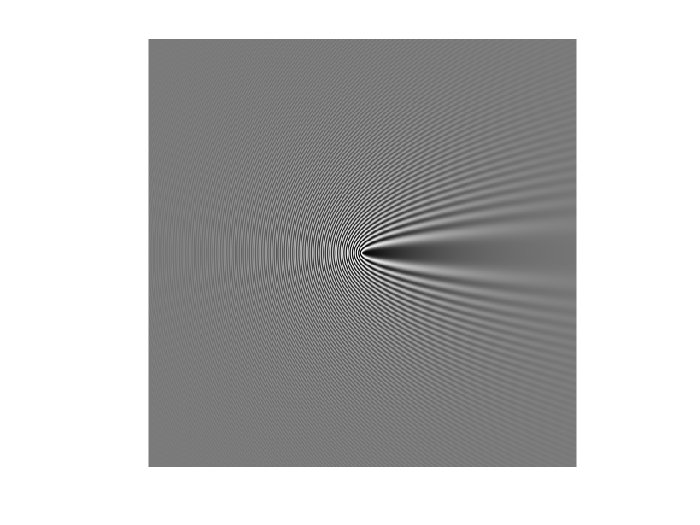

%% 生成干涉散射场
clear;
theta = 70.5;
n = 1.5;
lambda = 680;
kapa = 8;
phi = pi;
scale_factor = 0.1;
M_size = 501;
theta_spp = 0;
theta_res = 70.5;
[Ei,Es,F,I] = wave_generate(lambda,n,kapa,theta,phi,scale_factor,M_size,theta_spp,theta_res);
figure;imagesc(I);axis off; axis equal; colormap('gray'); 

# **提取颗粒图像**

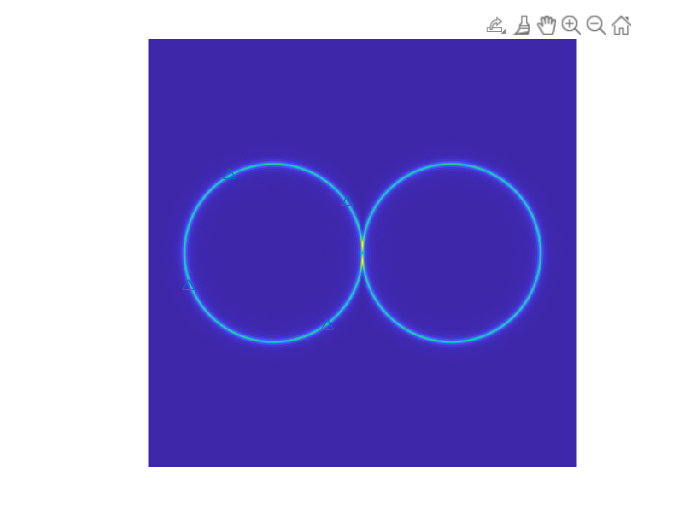

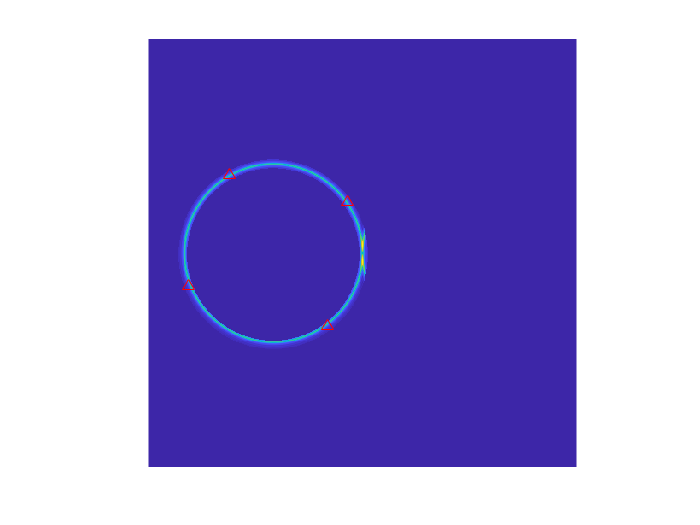

% 上面一步只是为了生成一个图像来演示，你可以直接把 I 赋
% 值成你的图像，然后 F = fftshift(fft2(fftshift(I)))
[center_raw,center_col,R,~] = findcircle((abs(F)),5,0,0);

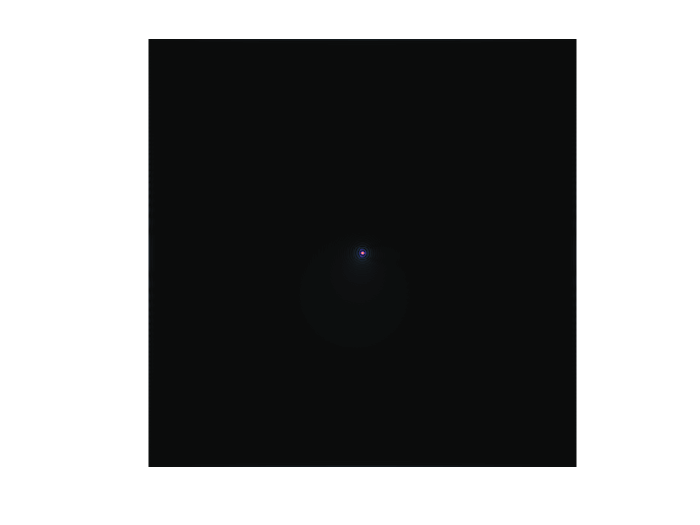

peaks = [center_col,center_raw,R];

mask = EwaldMask(F,peaks,0.2,'G',1,'in');
I_rcn = abs(ifftshift(ifft2(ifftshift(F.*mask))));
figure
imagesc(abs(I_rcn))
axis off
axis equal
